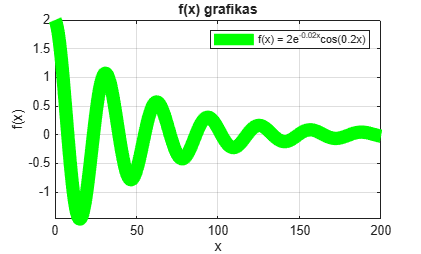

%1
figure(1);
x = linspace(0, 200, 300);

f1 = 2*exp(-0.02*x) .* cos(0.2*x);

plot(x, f1, 'g', 'LineWidth', 10);
grid on;
title('f(x) grafikas');
xlabel('x');
ylabel('f(x)');
axis([min(x) max(x) min(f1) max(f1)])
legend('f(x) = 2e^{-0.02x}cos(0.2x)', 'Location', 'northeast');

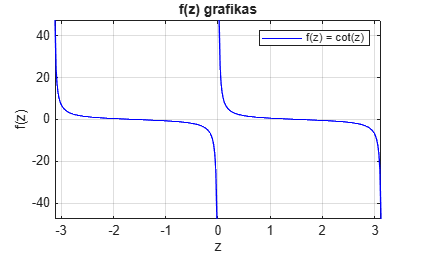


figure(2);

z1 = linspace(-pi, 0, 150);
z2 = linspace(0, pi, 150);

z1 = z1(2:end-1);
z2 = z2(2:end-1);

f21 = cot(z1);
f22 = cot(z2);

f2 = [f21, f22];
z = [z1, z2];

plot(z1, f21, 'b', z2, f22, 'b');
grid on;
title('f(z) grafikas');
xlabel('z');
ylabel('f(z)');
axis([min(z) max(z) min(f2) max(f2)])
legend('f(z) = cot(z)', 'Location', 'northeast');

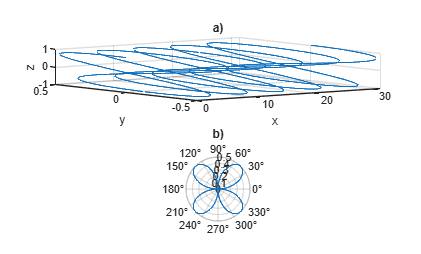

%2
clear
close all

figure(3);

x = 0:0.01:10*pi;

y = sin(x) .* cos(x);
z = cos(x);

subplot(2, 1, 1);

plot3(x, y, z);
grid on;
title('a)');
xlabel('x');
ylabel('y');
zlabel('z');

subplot(2, 1, 2);
polarplot(x, y);
title('b)');

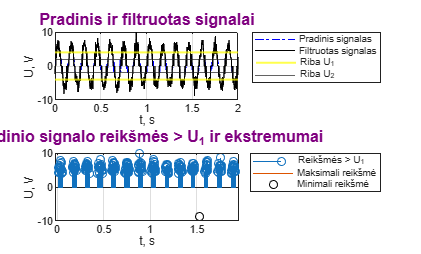

%Papildoma
clear
close all

A = 6; f = 7; sigma = 1.2; U1 = 4; U2 = 2;
t = 0:0.002:2;

s = A * sin(2*pi*f*t);
n = sigma*randn(size(t));
triuksmas = s + n;

filtruotas = triuksmas;
filtruotas(abs(filtruotas) < U2) = 0;

figure(4);
subplot(2, 1, 1);
plot(t, triuksmas, 'b-.');
hold on;
plot(t, filtruotas, 'k-');
yline(U1, 'y', 'LineWidth', 1.5);
yline(-U1, 'y', 'LineWidth', 1.5);
yline(U2);
yline(-U2);
grid on;
title('Pradinis ir filtruotas signalai', 'Color', [0.5 0 0.5], 'FontSize', 12);
xlabel('t, s')
ylabel('U, V')
legend('Pradinis signalas', 'Filtruotas signalas', 'Riba U_1', '', 'Riba U_2', 'Location', 'northeastoutside');


ind_U1 = triuksmas > U1; 
t_U1 = t(ind_U1);
triuksmas_U1 = triuksmas(ind_U1);

[max_val, max_idx] = max(triuksmas);
[min_val, min_idx] = min(triuksmas);

subplot(2, 1, 2);

stem(t_U1, triuksmas_U1);
hold on;
plot(t(max_idx), max_val);
plot(t(min_idx), min_val, 'ko');
hold off;
grid on;
title('Pradinio signalo reikšmės > U_1 ir ekstremumai', 'Color', [0.5 0 0.5], 'FontSize', 12);
xlabel('t, s');
ylabel('U, V');
legend('Reikšmės > U_1', 'Maksimali reikšmė', 'Minimali reikšmė', 'Location', 'northeastoutside');